% =========================================================================
% 程序名称：MATLAB 2D热传导计算结果验证程序
% 编写者：DeepSeek（深度求索AI助手）
% 编写时间：2025年11月2日
% 功能说明：从structured_mesh对象直接读取温度场数据，与参考数据进行对比验证
% 
% 输入要求：
%   - 需要先运行热传导仿真主程序，确保mesh对象存在于工作空间
%   - 参考数据包含x=0.5和x=0.0833两个位置的温度分布，来源于
%       https://www.theseus-fe.com/resources/validations/basic-heat-transfer
%     的2D conduction in rectangular plate示例
% 
% 输出内容：
%   - 详细的数据对比表格
%   - 误差统计分析
%   - 多维度可视化比较图表
%   - 一致性判断结果
% =========================================================================

% 参考数据 (x=0.5位置)
ref_x05_y = [0.0008968609865470656, 0.08071748878923765, 0.16412556053811653, ...
             0.2466367713004484, 0.33004484304932724, 0.41524663677130036, ...
             0.49865470852017924, 0.5820627802690582, 0.6654708520179371, ...
             0.7479820627802689, 0.8295964125560537];
             
ref_x05_t = [100, 97.5798319327731, 94.62184873949579, 91.12605042016806, ...
             86.55462184873949, 80.90756302521008, 73.78151260504201, ...
             64.23529411764704, 51.86554621848739, 37.07563025210084, ...
             21.344537815126046] + 273.15;

% 参考数据 (x=0.083位置)
ref_x0083_y = [0.0008968609865470656, 0.08161434977578474, 0.16502242152466365, ...
               0.24843049327354252, 0.3309417040358744, 0.41524663677130036, ...
               0.49775784753363217, 0.580269058295964, 0.6609865470852017, ...
               0.748878923766816, 0.8313901345291478];
               
ref_x0083_t = [100, 99.05882352941175, 97.98319327731092, 96.90756302521008, ...
               95.69747899159663, 93.41176470588235, 90.58823529411764, ...
               86.28571428571428, 78.48739495798318, 61.008403361344534, ...
               21.74789915966386] + 273.15;

% 假设mesh对象已经存在于工作空间中
if ~exist('mesh', 'var')
    error('错误：未找到mesh对象。请先运行热传导仿真。');
end

% 从mesh对象获取数据
xc = mesh.xc;
yc = mesh.yc;
t_field = mesh.t;  % 温度场 [ncx, ncy, ncz]

% 假设mesh对象已经存在于工作空间中
if ~exist('mesh', 'var')
    error('错误：未找到mesh对象。请先运行热传导仿真。');
end

% 从mesh对象获取数据
xc = mesh.xc;
yc = mesh.yc;
t_field = mesh.t;  % 温度场 [ncx, ncy, ncz]

% 找到最接近的x坐标位置
[~, idx_x05] = min(abs(xc - 0.5));
[~, idx_x0083] = min(abs(xc - 0.083));

fprintf('找到的x位置索引: x=0.5 -> %d (%.6f), x=0.083 -> %d (%.6f)\n', ...
        idx_x05, xc(idx_x05), idx_x0083, xc(idx_x0083));

找到的x位置索引: x=0.5 -> 61 (0.503965), x=0.083 -> 10 (0.079135)



% 提取MATLAB计算的温度数据 - 使用线性插值获取精确位置温度
matlab_x05_y = yc;

% 对x=0.5位置进行线性插值
if abs(xc(idx_x05) - 0.5) > 1e-6
    % 如果找到的索引位置不是精确的0.5，进行线性插值
    if xc(idx_x05) < 0.5 && idx_x05 < length(xc)
        x1 = xc(idx_x05);
        x2 = xc(idx_x05 + 1);
        t1 = squeeze(t_field(idx_x05, :, 1));
        t2 = squeeze(t_field(idx_x05 + 1, :, 1));
        weight = (0.5 - x1) / (x2 - x1);
        matlab_x05_t = t1 + weight * (t2 - t1);
        fprintf('x=0.5位置使用线性插值: %.6f -> %.6f (权重: %.4f)\n', x1, x2, weight);
    elseif xc(idx_x05) > 0.5 && idx_x05 > 1
        x1 = xc(idx_x05 - 1);
        x2 = xc(idx_x05);
        t1 = squeeze(t_field(idx_x05 - 1, :, 1));
        t2 = squeeze(t_field(idx_x05, :, 1));
        weight = (0.5 - x1) / (x2 - x1);
        matlab_x05_t = t1 + weight * (t2 - t1);
        fprintf('x=0.5位置使用线性插值: %.6f -> %.6f (权重: %.4f)\n', x1, x2, weight);
    else
        matlab_x05_t = squeeze(t_field(idx_x05, :, 1));
    end
else
    matlab_x05_t = squeeze(t_field(idx_x05, :, 1));
end

x=0.5位置使用线性插值: 0.495635 -> 0.503965 (权重: 0.5240)



matlab_x0083_y = yc;

% 对x=0.083位置进行线性插值
if abs(xc(idx_x0083) - 0.083) > 1e-6
    % 如果找到的索引位置不是精确的0.083，进行线性插值
    if xc(idx_x0083) < 0.083 && idx_x0083 < length(xc)
        x1 = xc(idx_x0083);
        x2 = xc(idx_x0083 + 1);
        t1 = squeeze(t_field(idx_x0083, :, 1));
        t2 = squeeze(t_field(idx_x0083 + 1, :, 1));
        weight = (0.083 - x1) / (x2 - x1);
        matlab_x0083_t = t1 + weight * (t2 - t1);
        fprintf('x=0.0833位置使用线性插值: %.6f -> %.6f (权重: %.4f)\n', x1, x2, weight);
    elseif xc(idx_x0083) > 0.083 && idx_x0083 > 1
        x1 = xc(idx_x0083 - 1);
        x2 = xc(idx_x0083);
        t1 = squeeze(t_field(idx_x0083 - 1, :, 1));
        t2 = squeeze(t_field(idx_x0083, :, 1));
        weight = (0.083 - x1) / (x2 - x1);
        matlab_x0083_t = t1 + weight * (t2 - t1);
        fprintf('x=0.0833位置使用线性插值: %.6f -> %.6f (权重: %.4f)\n', x1, x2, weight);
    else
        matlab_x0083_t = squeeze(t_field(idx_x0083, :, 1));
    end
else
    matlab_x0083_t = squeeze(t_field(idx_x0083, :, 1));
end

x=0.0833位置使用线性插值: 0.079135 -> 0.087465 (权重: 0.4640)



% 使用MATLAB内置函数进行插值
matlab_interp_x05_t = interp1(matlab_x05_y, matlab_x05_t, ref_x05_y, 'pchip', 'extrap')

matlab_interp_x05_t =   373.1114  369.6571  365.8768  361.7636  356.9595  351.0083  343.6941  334.3847  322.6488  308.6417  293.2272


matlab_interp_x0083_t = interp1(matlab_x0083_y, matlab_x0083_t, ref_x0083_y, 'pchip', 'extrap');

% 计算误差
error_x05 = abs(matlab_interp_x05_t - ref_x05_t);
error_x0083 = abs(matlab_interp_x0083_t - ref_x0083_t);

% 计算相对误差（避免除以零）
rel_error_x05 = error_x05 ./ (ref_x05_t + eps) * 100;
rel_error_x083 = error_x0083 ./ (ref_x0083_t + eps) * 100;

% 显示结果
fprintf('\n=== x=0.5位置验证结果 ===\n');


=== x=0.5位置验证结果 ===


fprintf('Y坐标\t\t参考温度\tMATLAB温度\t绝对误差\t相对误差(%%)\n');

Y坐标		参考温度	MATLAB温度	绝对误差	相对误差(%)


for i = 1:length(ref_x05_y)
    fprintf('%.6f\t%.6f\t%.6f\t%.6f\t%.6f\n', ...
            ref_x05_y(i), ref_x05_t(i), matlab_interp_x05_t(i), ...
            error_x05(i), rel_error_x05(i));
end

0.000897	373.150000	373.111430	0.038570	0.010336
0.080717	370.729832	369.657082	1.072750	0.289362
0.164126	367.771849	365.876816	1.895033	0.515274
0.246637	364.276050	361.763605	2.512446	0.689709
0.330045	359.704622	356.959453	2.745168	0.763173
0.415247	354.057563	351.008253	3.049310	0.861247
0.498655	346.931513	343.694142	3.237370	0.933144
0.582063	337.385294	334.384731	3.000563	0.889358
0.665471	325.015546	322.648809	2.366737	0.728192
0.747982	310.225630	308.641737	1.583893	0.510562
0.829596	294.494538	293.227166	1.267372	0.430355



fprintf('\n=== x=0.0833位置验证结果 ===\n');


=== x=0.0833位置验证结果 ===


fprintf('Y坐标\t\t参考温度\tMATLAB温度\t绝对误差\t相对误差(%%)\n');

Y坐标		参考温度	MATLAB温度	绝对误差	相对误差(%)


for i = 1:length(ref_x0083_y)
    fprintf('%.6f\t%.6f\t%.6f\t%.6f\t%.6f\n', ...
            ref_x0083_y(i), ref_x0083_t(i), matlab_interp_x0083_t(i), ...
            error_x0083(i), rel_error_x083(i));
end

0.000897	373.150000	373.137450	0.012550	0.003363
0.081614	372.208824	371.999963	0.208861	0.056114
0.165022	371.133193	370.762766	0.370428	0.099810
0.248430	370.057563	369.384120	0.673443	0.181983
0.330942	368.847479	367.766744	1.080735	0.293003
0.415247	366.561765	365.659980	0.901785	0.246012
0.497758	363.738235	362.808719	0.929516	0.255545
0.580269	359.435714	358.462683	0.973032	0.270711
0.660987	351.637395	351.056717	0.580678	0.165135
0.748879	334.158403	333.166079	0.992325	0.296962
0.831390	294.897899	292.234368	2.663531	0.903205



% 统计信息
fprintf('\n=== 统计信息 ===\n');


=== 统计信息 ===


fprintf('x=0.5位置:\n');

x=0.5位置:


fprintf('  最大绝对误差: %.6f\n', max(error_x05));

  最大绝对误差: 3.237370


fprintf('  最大相对误差: %.6f%%\n', max(rel_error_x05));

  最大相对误差: 0.933144%


fprintf('  平均绝对误差: %.6f\n', mean(error_x05));

  平均绝对误差: 2.069928


fprintf('  平均相对误差: %.6f%%\n', mean(rel_error_x05));

  平均相对误差: 0.601883%


fprintf('  均方根误差: %.6f\n', sqrt(mean(error_x05.^2)));

  均方根误差: 2.278165



fprintf('\nx=0.0833位置:\n');


x=0.0833位置:


fprintf('  最大绝对误差: %.6f\n', max(error_x0083));

  最大绝对误差: 2.663531


fprintf('  最大相对误差: %.6f%%\n', max(rel_error_x083));

  最大相对误差: 0.903205%


fprintf('  平均绝对误差: %.6f\n', mean(error_x0083));

  平均绝对误差: 0.853353


fprintf('  平均相对误差: %.6f%%\n', mean(rel_error_x083));

  平均相对误差: 0.251986%


fprintf('  均方根误差: %.6f\n', sqrt(mean(error_x0083.^2)));

  均方根误差: 1.080522


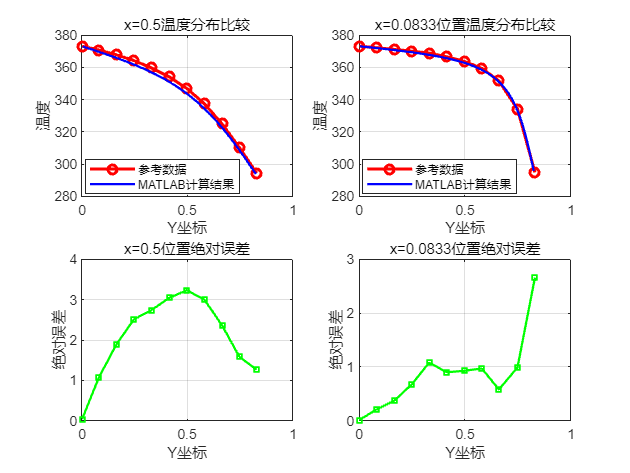


% 可视化比较
figure;

subplot(2,2,1);
plot(ref_x05_y, ref_x05_t, 'ro-', 'LineWidth', 2, 'MarkerSize', 6, 'DisplayName', '参考数据');
hold on;
plot(matlab_x05_y, matlab_x05_t, 'b-', 'LineWidth', 1.5, 'DisplayName', 'MATLAB计算结果');
xlabel('Y坐标');
ylabel('温度');
title('x=0.5温度分布比较')
legend('Location', 'best');
grid on;

subplot(2,2,2);
plot(ref_x0083_y, ref_x0083_t, 'ro-', 'LineWidth', 2, 'MarkerSize', 6, 'DisplayName', '参考数据');
hold on;
plot(matlab_x0083_y, matlab_x0083_t, 'b-', 'LineWidth', 1.5, 'DisplayName', 'MATLAB计算结果');
xlabel('Y坐标');
ylabel('温度');
title('x=0.0833位置温度分布比较');
legend('Location', 'best');
grid on;

% 误差分析
subplot(2,2,3);
plot(ref_x05_y, error_x05, 'g-s', 'LineWidth', 1.5, 'MarkerSize', 4);
xlabel('Y坐标');
ylabel('绝对误差');
title('x=0.5位置绝对误差');
grid on;

subplot(2,2,4);
plot(ref_x0083_y, error_x0083, 'g-s', 'LineWidth', 1.5, 'MarkerSize', 4);
xlabel('Y坐标');
ylabel('绝对误差');
title('x=0.0833位置绝对误差');
grid on;



fprintf('\n验证完成！\n');


验证完成！
